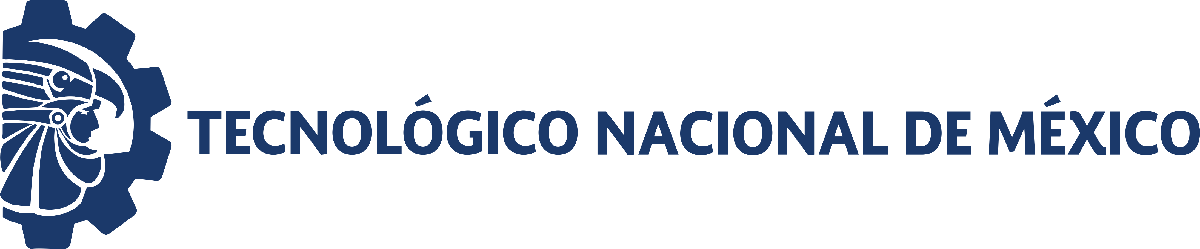                                 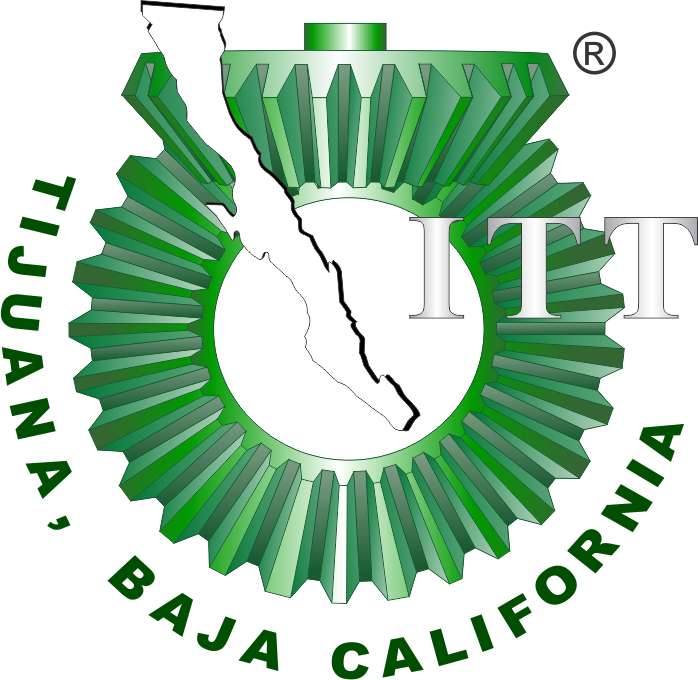

# Práctica 3: Sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

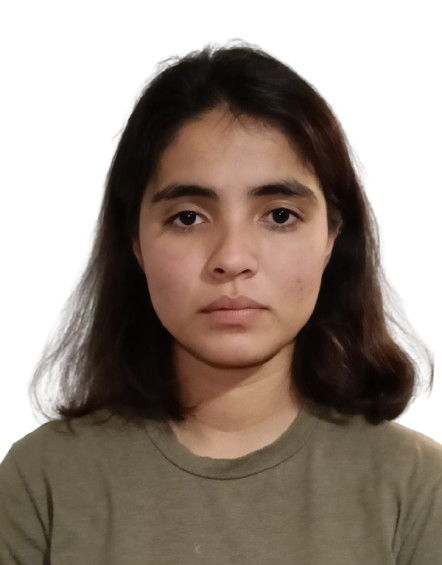

Nombre del alumno: Vania Daniela Rivera Durán

Número de control: C22211720

Correo institucional: L22211720**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file= 'Sistema';
open_system(file);
parameters.StopTime=tend;
parameters.Solver='ode15s';
parameters.MaxStep='1E-3';
x = sim(file,parameters);

## Respuesta del sistema

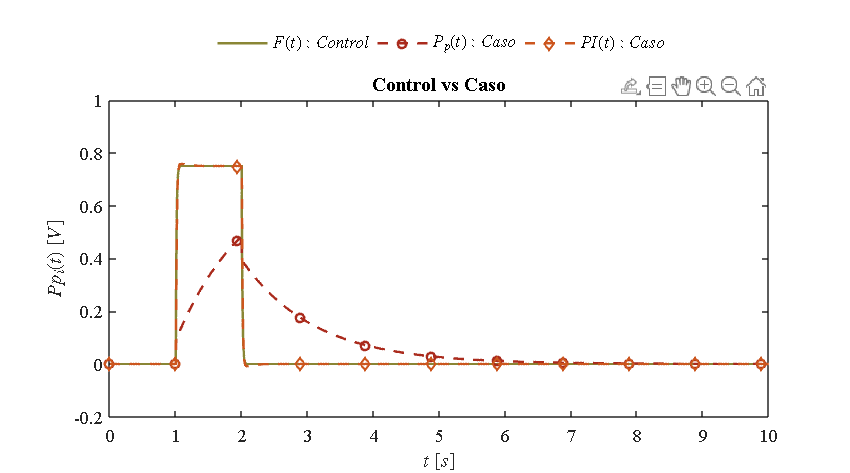

plotsignals(x.t,x.Pp1,x.Pp2,x.PI)

## Función: Respuesta a las señales

function plotsignals(t,Pp1,Pp2,PI)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,10])
    colors = [138, 134, 53;
              170, 43, 29;
              204, 86, 30]/255;
    colororder(colors)

    hold on; box on;
    plot(t,Pp1,'-',t,Pp2,'--o',t,PI,'--d','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    L=legend('$F(t): Control$','$P_p(t): Caso$','$PI(t): Caso$');
    set(L,'Interpreter','Latex','FontSize',10,'Location','NorthOutside','box','off','Orientation','Horizontal')
    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$Pp_i(t)$ $[V]$','Interpreter','Latex','FontSize',11)
    xlim([0,10]);xticks(0:1:15);
    ylim([-0.2,1]);yticks(-0.2:0.2:1);
    T = title("Control vs Caso"); set(T,'FontSize',10);
    set(gca,'FontName','Times New Roman','FontSize',11);



    exportgraphics(gcf,'Musculoesqueletico.pdf','ContentType','vector')
    %exportgraphics(gcf,[Signal,'.png'],'Resolution',600)
    %print(Signal, '-dsvg', '-r600')
    %print(Signal, '-depsc', '-r600')

end